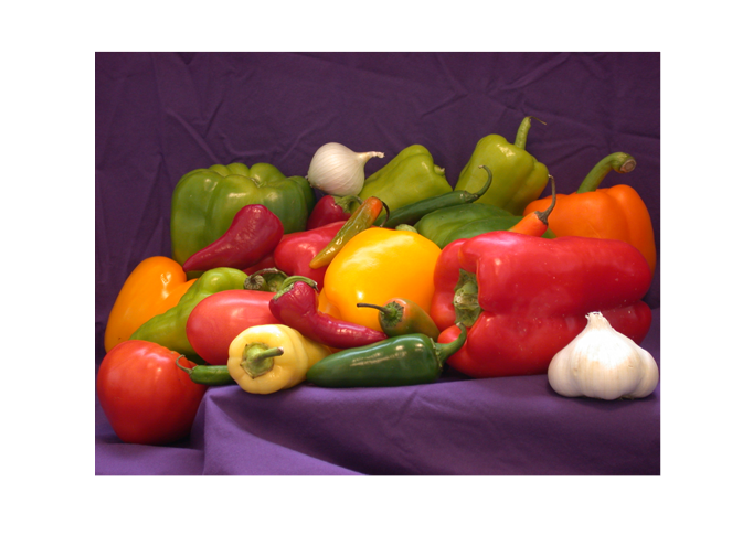

% 1 1. Завантажте з бібліотеки MATLAB декілька кольорових і чорно-білих
% зображень різного характеру (що містять великі й дрібні елементи).
% 2. З використанням функції rgb2gray перетворіть кольорові зображення
% в чорно-білі. Відобразіть результат.
F1 = imread('peppers.png');
F2 = imread('cameraman.tif');

figure;
imshow(F1);

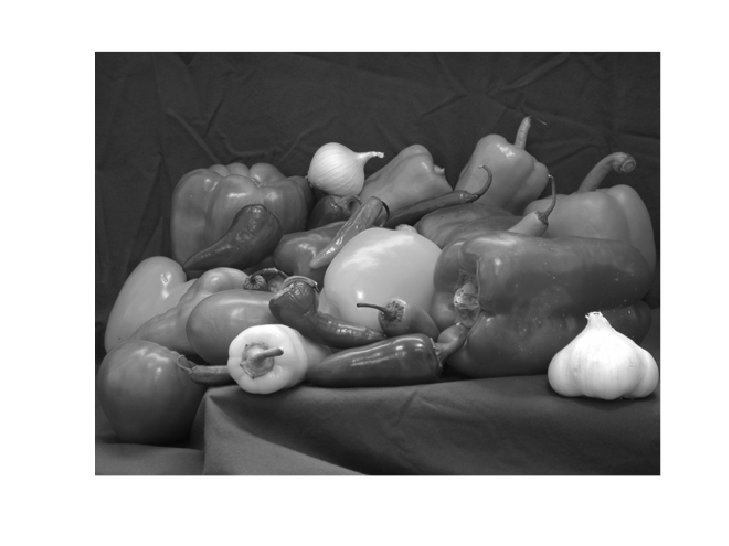

I1 = rgb2gray(F1);
I2 = F2;

figure;
imshow(I1);

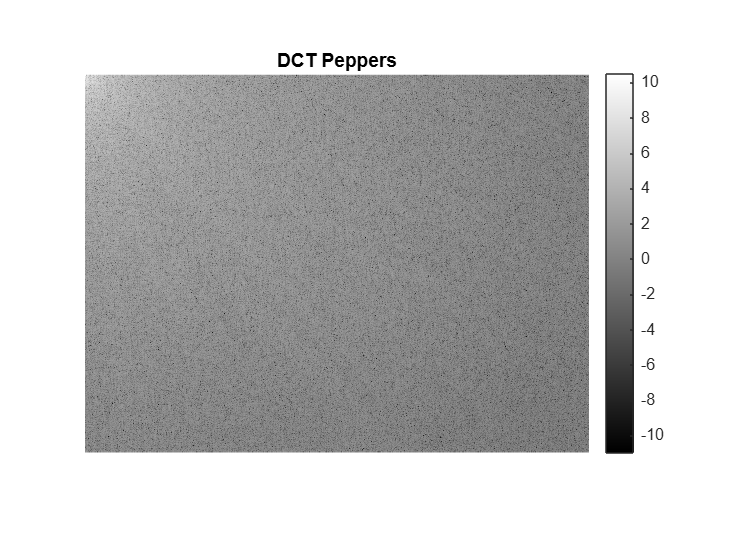

% З використанням функції dct2 виконайте дискретне косинусне
% перетворення зображень. Відобразіть результат ДКП у вигляді зображення з
% використанням функції imshow. Під час відображенні масиву ДКП-коефіцієнтів
% використовуйте логарифмічний масштаб.

J1 = dct2(I1);
J2 = dct2(I2);

figure;
imshow(log(abs(J1)),[]); colorbar; title('DCT Peppers');

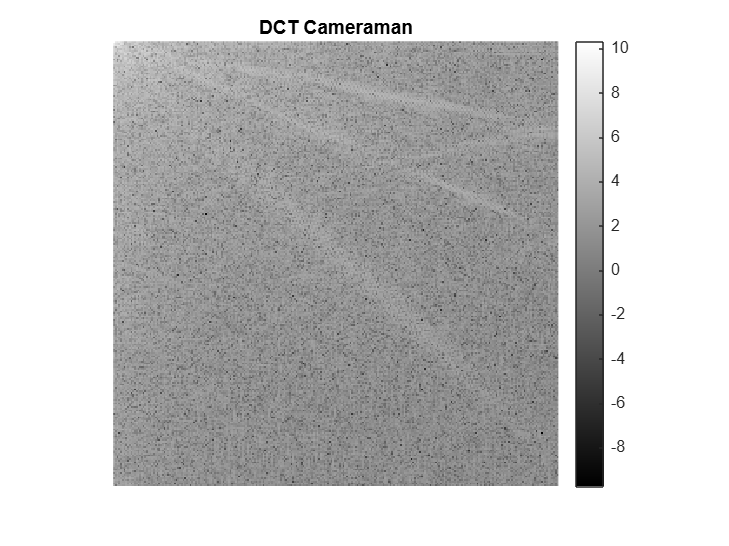

imshow(log(abs(J2)),[]); colorbar; title('DCT Cameraman');

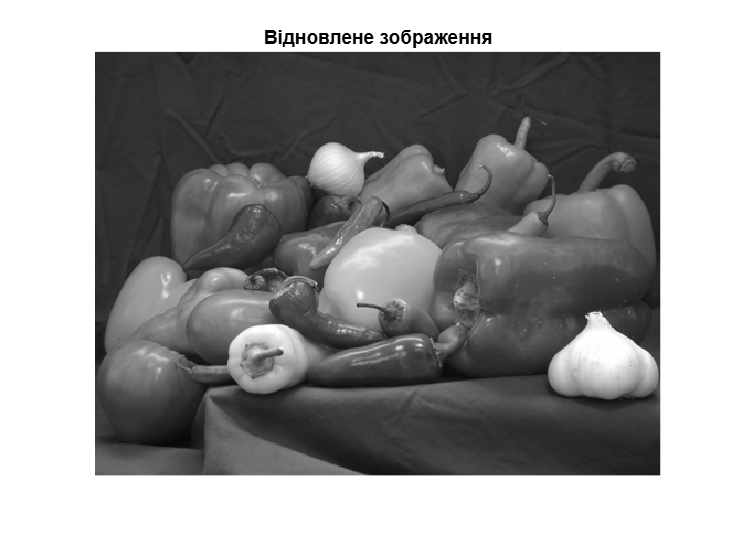

% 4. З використанням функції idct2 відновіть зображення за його ДКП-спектру.
K1 = idct2(J1);

figure;
imshow(K1, [0 255]), title('Відновлене зображення');

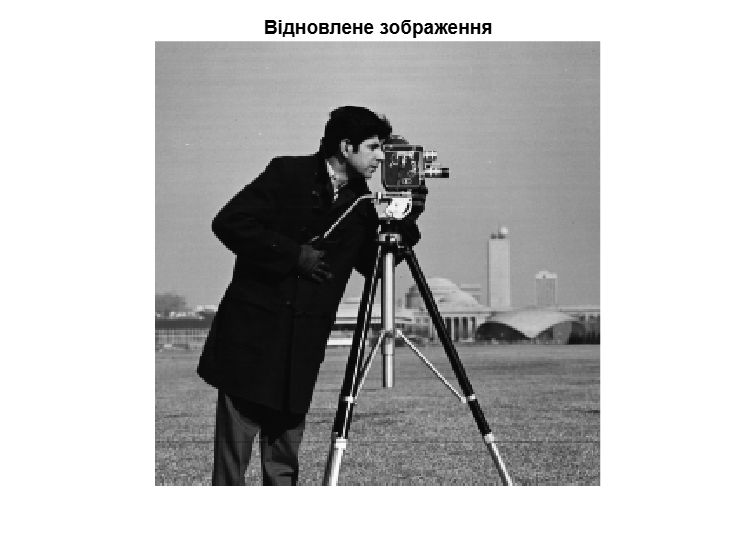

% 4. З використанням функції idct2 відновіть зображення за його ДКП-спектру.
K2 = idct2(J2);

figure;
imshow(K2, [0 255]), title('Відновлене зображення');

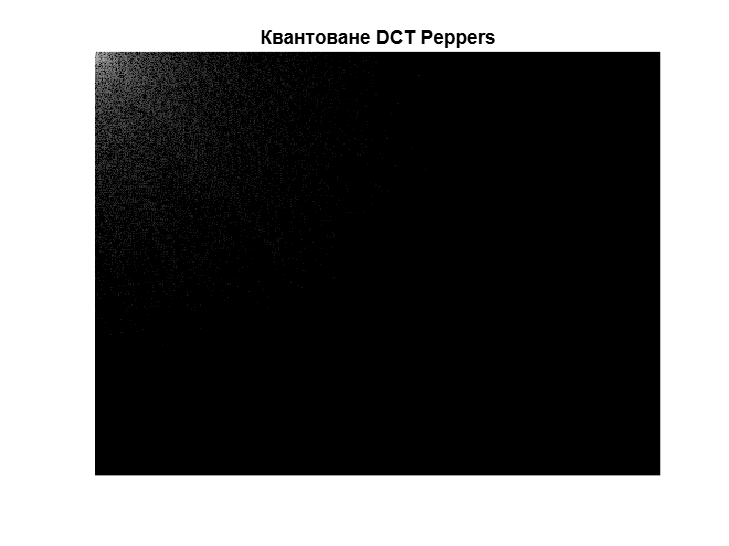

% З використанням процедури целочислового ділення/множення J =
% N*round(J*N); виконайте квантування результатів ДКП для різних значень
% кроку квантування N. Поясніть, як працює ця процедура, і що отримаємо в
% результаті.
N = 10; 

% Квантування
J1_quant = N*round(J1/N);
J2_quant = N*round(J2/N);

figure;
imshow(log(abs(J1_quant)),[]); title('Квантоване DCT Peppers')

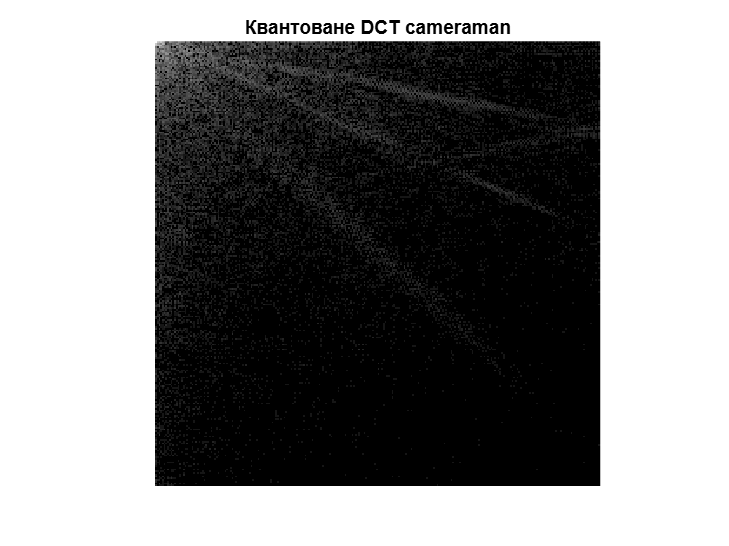

figure;
imshow(log(abs(J2_quant)),[]); title('Квантоване DCT cameraman')

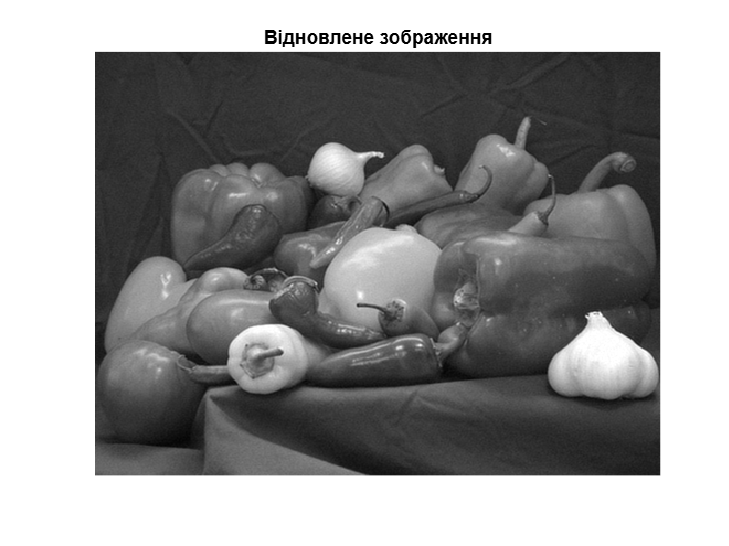


% 7. З використанням функції idct2 відновіть зображення за квантованим
% ДКП-спектром для різних значень кроку квантування. Поясніть отримані
% результати.

K1_quant = idct2(J1_quant);
K2_quant = idct2(J2_quant);

figure;
imshow(K1_quant,[0 255]); title('Відновлене зображення');

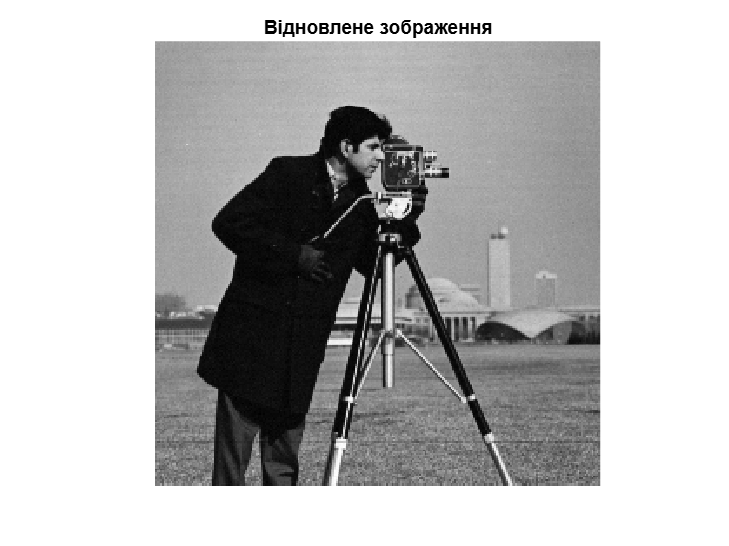

imshow(K2_quant,[0 255]); title('Відновлене зображення');

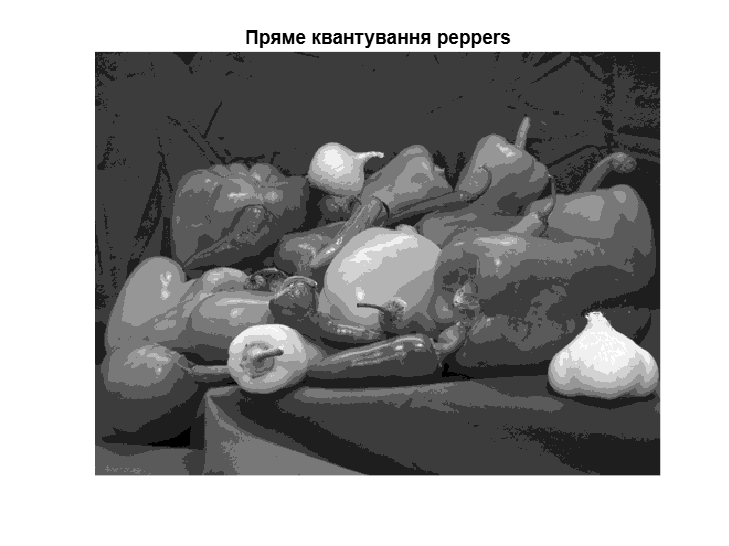


% Чи можливо добитися аналогічної мети й результату, квантуючи
% вихідне зображення, а не коефіцієнти його ДКП? Перевірте це на практиці,
% квантуючи з використанням процедури I = (round(J/n))*n вихідні
% зображення й відобразіть отриманий результат. Поясніть результат.

n = 30;
I1_quant = (round(double(I1)/n))*n;
I2_quant = (round(double(I2)/n))*n;

figure;
imshow(uint8(I1_quant)); title('Пряме квантування peppers');

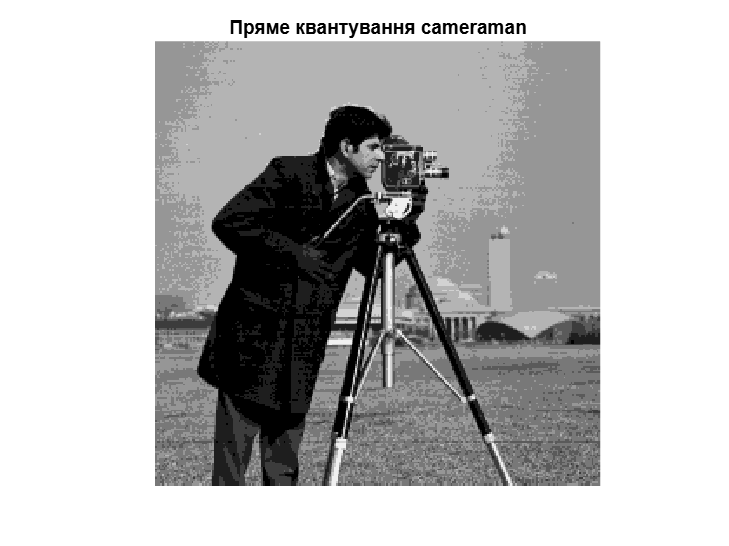

imshow(uint8(I2_quant)); title('Пряме квантування cameraman');